%% Initialization
clear ; close all; clc

fprintf('Finding closest centroids.\n\n');

Finding closest centroids.



tableRBs = readtable('2021RBs.csv');

RBs = tableRBs(1:63,:);

%Standard tiering
RBs_PTSandOPP = table2array(RBs(:,[3 6]))

RBs_PTSandOPP =   342.1000  366.0000
  282.4000  272.0000
  266.9000  340.0000
  256.2000  386.0000
  221.0000  264.0000
  218.9000  281.0000
  214.9000  220.0000
  206.9000  216.0000
  203.0000  236.0000
  198.8000  243.0000


K-Means iteration 1/3...


K-Means iteration 2/3...


K-Means iteration 3/3...


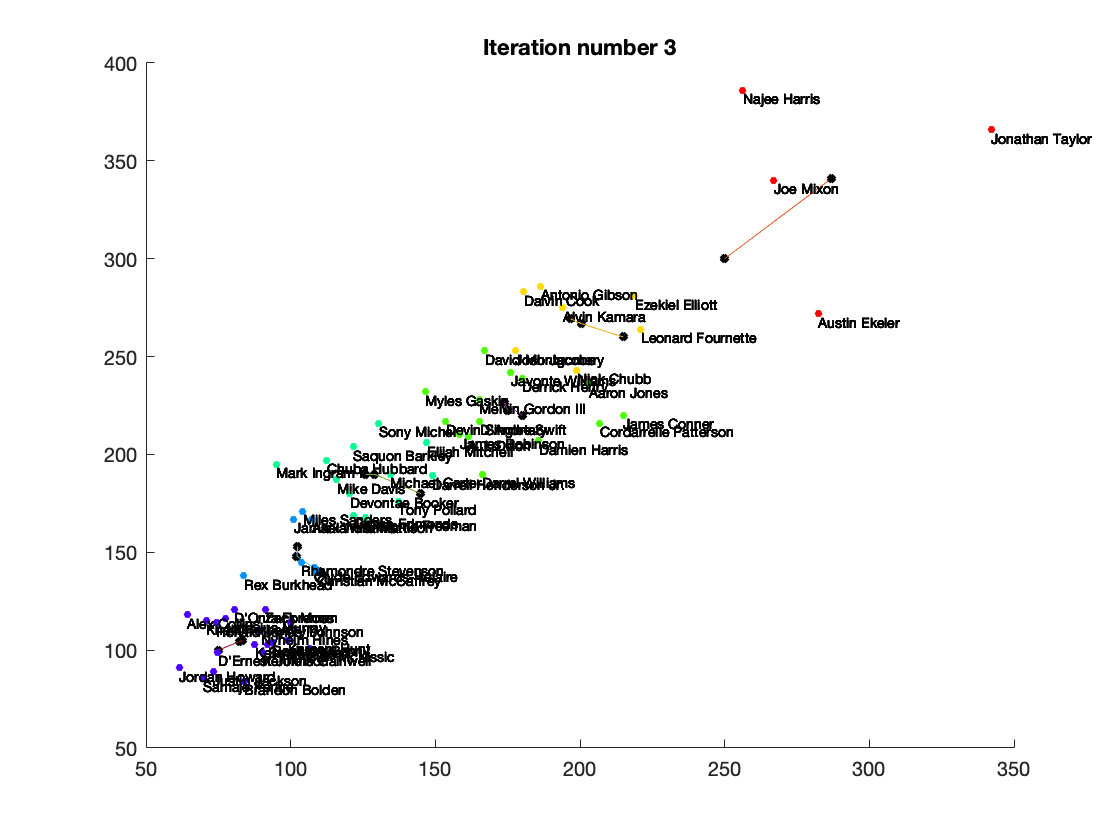

% Select an initial set of centroids
K_1 = 6; % 6 Centroids
max_iters_1 = 3;
initial_RBs_PTSvOPP_centroids = [250 300; 215 260; 180 220; 145 180; 110 140; 75 100];

idx_1 = findClosestCentroids(RBs_PTSandOPP,initial_RBs_PTSvOPP_centroids);
RBs_PTSvOPP_centroids = computeCentroids(RBs_PTSandOPP, idx_1, K_1);
[RBs_PTSvOPP_centroids, idx_1] = runkMeans(RBs_PTSandOPP, initial_RBs_PTSvOPP_centroids, max_iters_1, true);

%Regression Candidates (Higher tier means more likely to regress)
RBs_TOTTDandYPT = table2array(RBs(:,[18 19]))

RBs_TOTTDandYPT =    20.0000    5.8644
   18.0000    5.7216
   16.0000    4.5479
   10.0000    4.4044
   10.0000    5.0803
   12.0000    4.5245
   16.0000    4.7431
   11.0000    5.7700
   10.0000    5.3363
    9.0000    5.7689


K-Means iteration 1/8...


K-Means iteration 2/8...


K-Means iteration 3/8...


K-Means iteration 4/8...


K-Means iteration 5/8...


K-Means iteration 6/8...


K-Means iteration 7/8...


K-Means iteration 8/8...


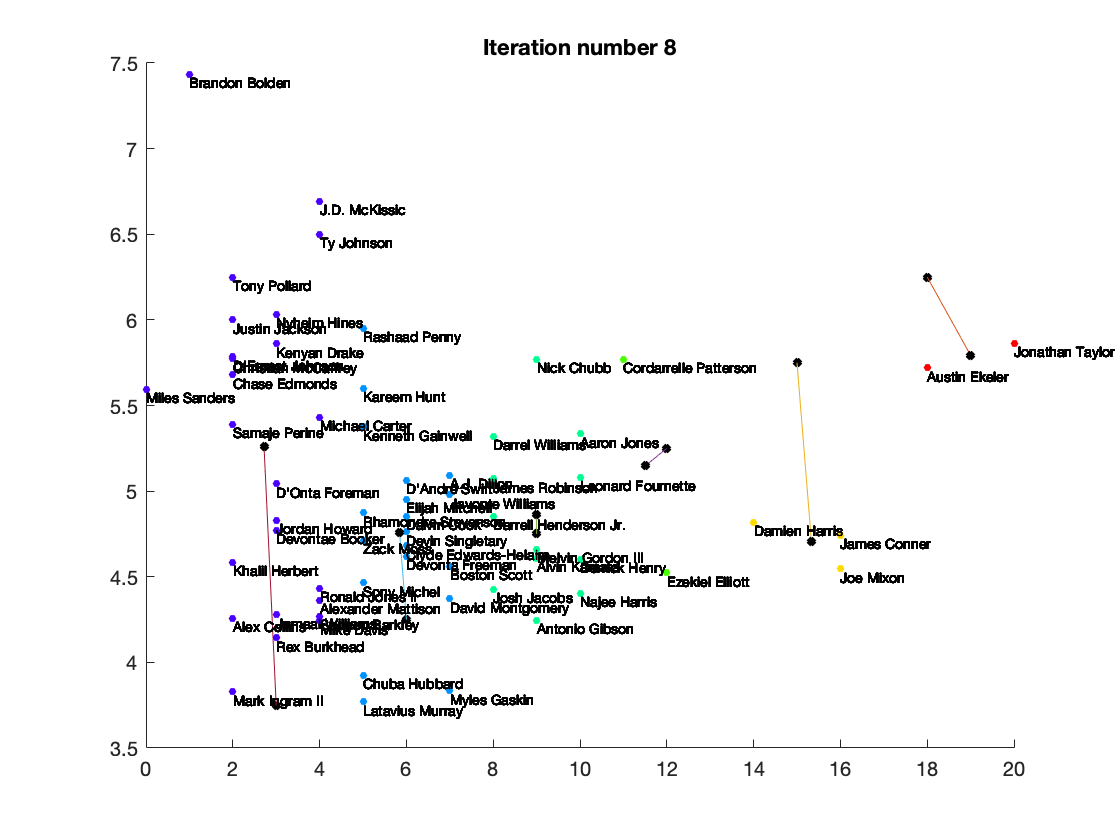

% Select an initial set of centroids
K_2 = 6; % 6 Centroids
max_iters_2 = 8;
initial_RBs_TOTTDvYPT_centroids = [18 6.25; 15 5.75; 12 5.25; 9 4.75; 6 4.25; 3 3.75];

idx_2 = findClosestCentroids(RBs_TOTTDandYPT,initial_RBs_TOTTDvYPT_centroids);
RBs_TOTTDvYPT_centroids = computeCentroids(RBs_TOTTDandYPT, idx_2, K_2);
[RBs_TOTTDvYPT_centroids, idx_2] = runkMeans(RBs_TOTTDandYPT, initial_RBs_TOTTDvYPT_centroids, max_iters_2, true);

%High Floor Candidates (Higher tier means less likely to regress)
RBs_PPGandTGT = table2array(RBs(:,[4 12]))

RBs_PPGandTGT =    21.4000   49.0000
   18.8000   82.0000
   16.7000   48.0000
   16.0000   90.0000
   15.8000   84.0000
   13.7000   62.0000
   15.3000   33.0000
   13.8000   67.0000
   13.5000   65.0000
   15.3000   24.0000


K-Means iteration 1/12...


K-Means iteration 2/12...


K-Means iteration 3/12...


K-Means iteration 4/12...


K-Means iteration 5/12...


K-Means iteration 6/12...


K-Means iteration 7/12...


K-Means iteration 8/12...


K-Means iteration 9/12...


K-Means iteration 10/12...


K-Means iteration 11/12...


K-Means iteration 12/12...


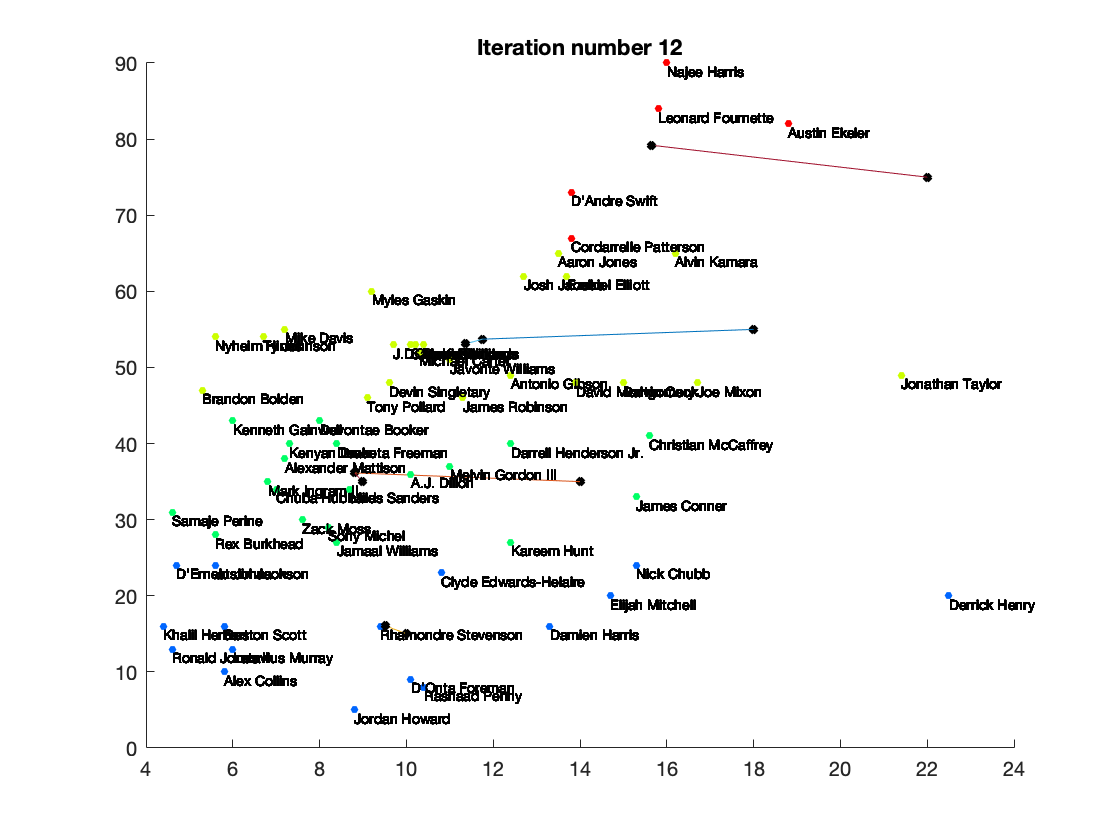

% Select an initial set of centroids
K_3 = 4; % 4 Centroids
max_iters_3 = 12;
initial_RBs_PPGvTGT_centroids = [22 75; 18 55; 14 35; 10 15];

idx_3 = findClosestCentroids(RBs_PPGandTGT,initial_RBs_PPGvTGT_centroids);
PPGvTGT_centroids = computeCentroids(RBs_PPGandTGT, idx_3, K_3);
[PPGvTGT_centroids, idx_3] = runkMeans(RBs_PPGandTGT, initial_RBs_PPGvTGT_centroids, max_iters_3, true);

function idx = findClosestCentroids(X, centroids)
%FINDCLOSESTCENTROIDS computes the centroid memberships for every example
%   idx = FINDCLOSESTCENTROIDS (X, centroids) returns the closest centroids
%   in idx for a dataset X where each row is a single example. idx = m x 1 
%   vector of centroid assignments (i.e. each entry in range [1..K])
%

K = size(centroids, 1);

idx = zeros(size(X,1), 1);


for i = 1:size(X,1)
    distance = 99999;
    for j = 1:K
        distance_current = norm(X(i,:)-centroids(j,:))^2;
        if distance_current < distance
            temp_j = j;
            distance = distance_current;
        end
    end
    idx(i) = temp_j;
end





% =============================================================

end


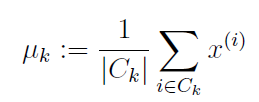

function centroids = computeCentroids(X, idx, K)
%COMPUTECENTROIDS returns the new centroids by computing the means of the 
%data points assigned to each centroid.
%   centroids = COMPUTECENTROIDS(X, idx, K) returns the new centroids by 
%   computing the means of the data points assigned to each centroid. It is
%   given a dataset X where each row is a single data point, a vector
%   idx of centroid assignments (i.e. each entry in range [1..K]) for each
%   example, and K, the number of centroids. You should return a matrix
%   centroids, where each row of centroids is the mean of the data points
%   assigned to it.
%

[m n] = size(X);

centroids = zeros(K, n);




for k = 1:K
    subset = X(idx==k,:);
    centroids(k,:) = mean(subset,1);
end







% =============================================================


end

function centroids = kMeansInitCentroids(X, K)
%KMEANSINITCENTROIDS This function initializes K centroids that are to be 
%used in K-Means on the dataset X
%   centroids = KMEANSINITCENTROIDS(X, K) returns K initial centroids to be
%   used with the K-Means on the dataset X
% 

centroids = zeros(K, size(X, 2));


ind = randperm(size(X,1));
centroids = X(ind(1:K),:);







% =============================================================

end



Appendix

function [centroids, idx] = runkMeans(X, initial_centroids, ...
                                      max_iters, plot_progress)
%RUNKMEANS runs the K-Means algorithm on data matrix X, where each row of X
%is a single example
%   [centroids, idx] = RUNKMEANS(X, initial_centroids, max_iters, ...
%   plot_progress) runs the K-Means algorithm on data matrix X, where each 
%   row of X is a single example. It uses initial_centroids used as the
%   initial centroids. max_iters specifies the total number of interactions 
%   of K-Means to execute. plot_progress is a true/false flag that 
%   indicates if the function should also plot its progress as the 
%   learning happens. This is set to false by default. runkMeans returns 
%   centroids, a Kxn matrix of the computed centroids and idx, a m x 1 
%   vector of centroid assignments (i.e. each entry in range [1..K])
%

% Set default value for plot progress
if ~exist('plot_progress', 'var') || isempty(plot_progress)
    plot_progress = false;
end

% Plot the data if we are plotting progress
if plot_progress
    figure;
    hold on;
end

% Initialize values
[m n] = size(X);
K = size(initial_centroids, 1);
centroids = initial_centroids;
previous_centroids = centroids;
idx = zeros(m, 1);

% Run K-Means
for i=1:max_iters
    
    % Output progress
    fprintf('K-Means iteration %d/%d...\n', i, max_iters);
    if exist('OCTAVE_VERSION')
        fflush(stdout);
    end
    
    % For each example in X, assign it to the closest centroid
    idx = findClosestCentroids(X, centroids);
    
    % Optionally, plot progress here
    if plot_progress
        plotProgresskMeans(X, centroids, previous_centroids, idx, K, i);
        previous_centroids = centroids;
        %fprintf('Press enter to continue.\n');
        %pause;
    end
    
    % Given the memberships, compute new centroids
    centroids = computeCentroids(X, idx, K);
end

% Hold off if we are plotting progress
if plot_progress
    hold off;
end

end

function plotProgresskMeans(X, centroids, previous, idx, K, i)
%PLOTPROGRESSKMEANS is a helper function that displays the progress of 
%k-Means as it is running. It is intended for use only with 2D data.
%   PLOTPROGRESSKMEANS(X, centroids, previous, idx, K, i) plots the data
%   points with colors assigned to each centroid. With the previous
%   centroids, it also plots a line between the previous locations and
%   current locations of the centroids.
%

% Plot the examples
plotDataPoints(X, idx, K);
tableRBs = readtable('2021RBs.csv');
RBs = tableRBs(1:63,:);
RBnames = table2cell(RBs(:,1));
text(X(:,1),X(:,2),RBnames,'VerticalAlignment','top','HorizontalAlignment','left','FontSize',7);


% Plot the centroids as black x's
plot(centroids(:,1), centroids(:,2), 'x', ...
     'MarkerEdgeColor','k', ...
     'MarkerSize', 2, 'LineWidth', 3);

% Plot the history of the centroids with lines
for j=1:size(centroids,1)
    drawLine(centroids(j, :), previous(j, :));
end

% Title
title(sprintf('Iteration number %d', i))

end
function plotDataPoints(X, idx, K)
%PLOTDATAPOINTS plots data points in X, coloring them so that those with the same
%index assignments in idx have the same color
%   PLOTDATAPOINTS(X, idx, K) plots data points in X, coloring them so that those 
%   with the same index assignments in idx have the same color

% Create palette
palette = hsv(K + 1);
colors = palette(idx, :);

% Plot the data
scatter(X(:,1), X(:,2), 15, colors,'filled');
tableRBs = readtable('2021RBs.csv');
RBs = tableRBs(1:63,:);
RBnames = table2cell(RBs(:,1));
text(X(:,1),X(:,2),RBnames,'VerticalAlignment','top','HorizontalAlignment','left','FontSize',7);
end

function drawLine(p1, p2, varargin)
%DRAWLINE Draws a line from point p1 to point p2
%   DRAWLINE(p1, p2) Draws a line from point p1 to point p2 and holds the
%   current figure

plot([p1(1) p2(1)], [p1(2) p2(2)], varargin{:});

end